# Step 12: データの入出力

系統モデルは、制御器とシナリオも含めてフォルダ（CSV の表とシナリオの JSON ファイル）に書き出し、読み込み直せます。MATPOWER のケースからも系統を作れます。解析の結果は、`Format` で表や構造体の形で受け取ったり、`export` でファイルに書き出したりできます。この Step では、これらの入口を順に扱います。

入出力は、GUILDA の基本的な流れの赤枠の部分に関わります（系統モデルの読み込み、シナリオの保存、結果の書き出し）。

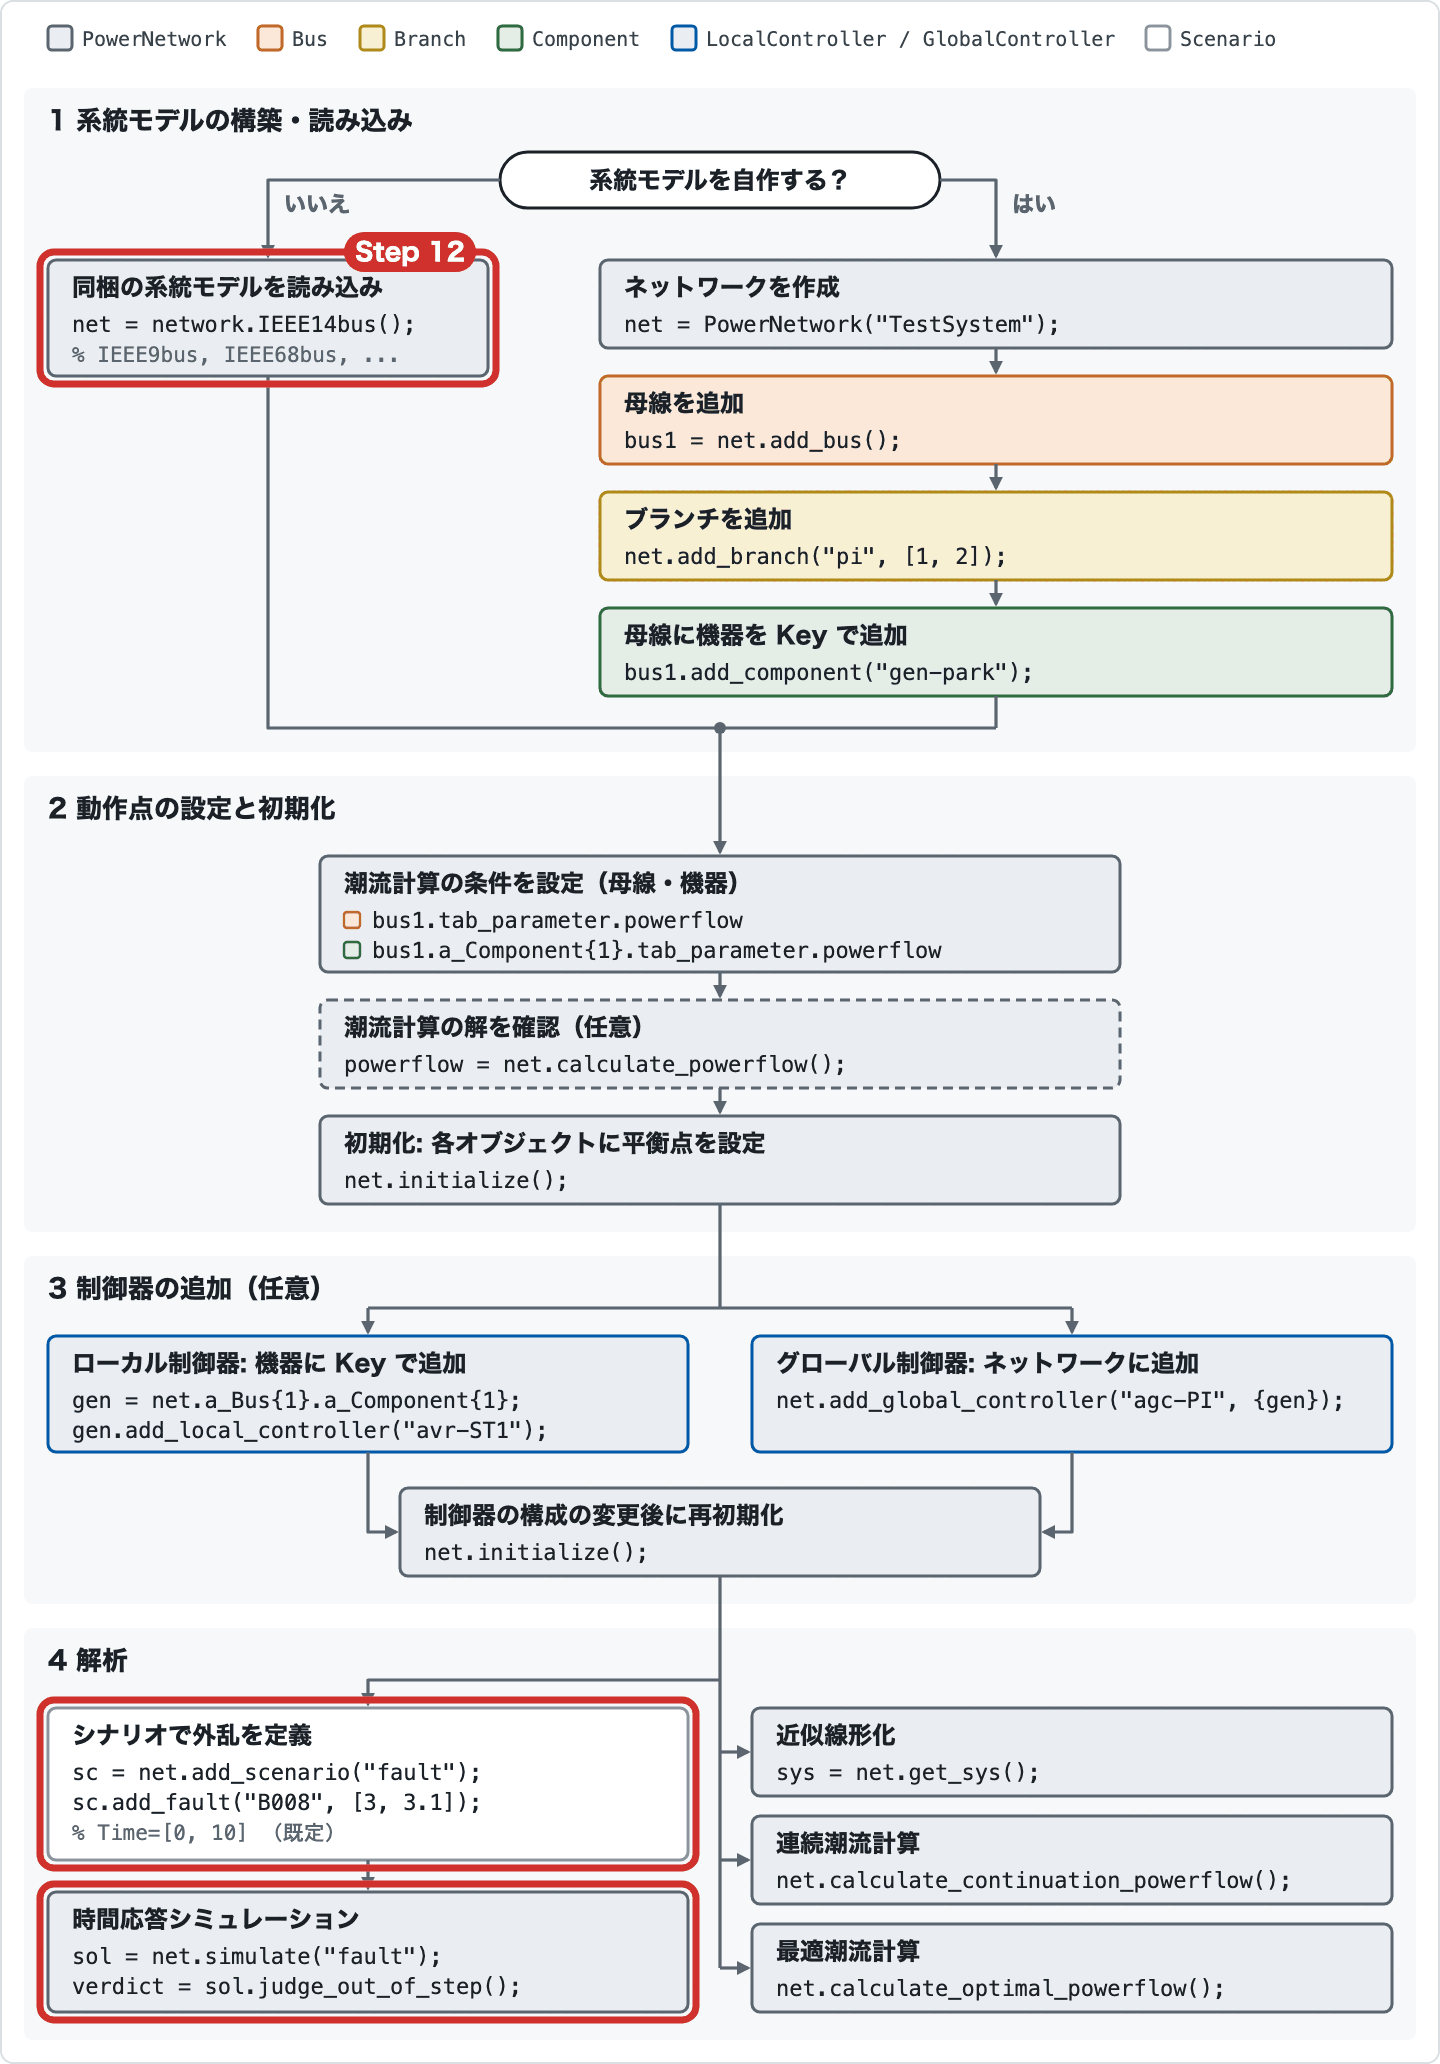

**この Step で分かること**

- 系統モデル（制御器を含む）とシナリオのフォルダへの書き出し（`net.export`）と読み込み（`PowerNetwork.import`）

- 書き出したフォルダの構成と、各ファイルの中身

- 系統をクラスとして保存する方法（`@` で始まるフォルダ）

- MATPOWER のケースからの読み込み（`PowerNetwork.import_matpower`）

- `Format` による結果の取り出し（潮流計算・時間シミュレーション・近似線形化）

- 結果のファイルへの書き出し（`result.export`）

各節は、ファイルを読み書きするのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

この Step で書き出すファイルは、すべて一時フォルダ（`tempdir`）の中に作り、最後に削除します。

s_work = fullfile(tempdir, "GUILDA_Step12");
if isfolder(s_work)
    rmdir(s_work, "s");
end
mkdir(s_work);

## 1. 系統とシナリオを準備する

IEEE 9 母線系統を読み込み、母線 8 の地絡を入れたシナリオを 1 つ加えます。各発電機には AVR（`avr-ST1`）、PSS（`pss-PSS1`）、ガバナ（`gov-static`）が付いています。制御器とシナリオも、系統と一緒に書き出されます。

net = network.IEEE9bus(LocalController=true);
net.initialize();
sc = net.add_scenario("fault1", Time=[0, 5], Description="母線 8 の地絡");
sc.add_fault("B008", [1, 1.05]);

**確かめる（省略できます）**

net.a_Scenario

ans = 1×1 の cell 配列
    {1×1 Scenario}


## 2. 系統モデルをフォルダに書き出す

`net.export(フォルダ)` で、系統をモデルフォルダに書き出します。フォルダは新しく作られます（親フォルダは先に存在している必要があります）。戻り値は書き出したフォルダのパスです。

s_model = net.export(fullfile(s_work, "MyIEEE9"));

書き出したフォルダは、次のファイルでできています。

**注意:** 同じフォルダがすでにあるとエラーになります。平衡点と、`initialize` で求める値（LQR のゲインなど）は保存されません。読み込み時の `initialize` で求め直します。上書きするオプションなど、その他のオプションは `export` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=export')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

書き出したファイルの一覧です。

sct_file = dir(fullfile(s_model, "**", "*.*"));
sct_file = sct_file(~[sct_file.isdir]);
erase(string({sct_file.folder}') + "/" + string({sct_file.name}'), s_model + "/")

ans = 13×1 の string 配列
    "branch/parameter.csv"
    "bus/parameter.csv"
    "component/gen-1axis/dynamics.csv"
    "component/gen-1axis/main.csv"
    "component/gen-1axis/opf.csv"
    "component/load-impedance/dynamics.csv"
    "component/load-impedance/main.csv"
    "component/load-impedance/opf.csv"
    "local_controller/avr-ST1/parameter.csv"
    "local_controller/gov-static/parameter.csv"
    "local_controller/pss-PSS1/parameter.csv"
    "network/parameter.csv"
    "scenario/fault1.json"


CSV は `readtable` で読めます。母線の表は 1 行が 1 母線で、`From`・`To`・`Bus` の母線番号はこの行の番号です。

readtable(fullfile(s_model, "bus", "parameter.csv"), TextType="string")

ans = 9×16 table
    Tag    FullTag      V      Varg    baseKV    Vmin    Vmax    Gshunt    Bshunt     X      Y      Shape      Length    MarkerSize    Color    Slack
    ___    _______    _____    ____    ______    ____    ____    ______    ______    ___    ___    ________    ______    __________    _____    _____

    "B"    "B001"      1.04     0       230      0.5     1.5       0         0       NaN    NaN    "square"     NaN         NaN         NaN       1  
    "B"    "B002"     1.025     0       230      0.5     1.5       0         0       NaN    NaN    "square"     NaN         NaN         NaN       0  
    "B"    "B003"     1.025     0       230      0.5     1.5       0         0       NaN    NaN    "square"     NaN         NaN         NaN       0  
    "B"    "B004"         1     0       230      0.5     1.5       0         0       NaN    NaN    "square"     NaN         NaN         NaN       0  
    "B"    "B005"         1     0       230      0.5     1.5       0         0    

ブランチの表です。

readtable(fullfile(s_model, "branch", "parameter.csv"), TextType="string")

ans = 9×19 table
          Type          From    To    FullTag      R         X         C       tap    phase    circuit    Smax    Imax    Pmax    Qmax    Vargmax    Path    FromOffset    ToOffset    Style 
    ________________    ____    __    _______    ______    ______    ______    ___    _____    _______    ____    ____    ____    ____    _______    ____    __________    ________    ______

    "pi_transformer"     1      4     "ET001"         0    0.0576         0      1       0        2       Inf     Inf     Inf     Inf     1.5708     NaN        NaN          NaN       "line"
    "pi_transformer"     2      7     "ET002"         0    0.0625         0      1       0        2       Inf     Inf     Inf     Inf     1.5708     NaN        NaN          NaN       "line"
    "pi_transformer"     3      9     "ET003"         0    0.0586         0      1       0        2       Inf     Inf     Inf     Inf     1.5708     NaN        NaN          NaN       "line"
    "pi"                 4      

発電機の表と、そのパラメータの表です。`main.csv` の `ParameterID` が `dynamics.csv` の行を指します。

readtable(fullfile(s_model, "component", "gen-1axis", "main.csv"), TextType="string")

ans = 3×18 table
    Bus     FullTag      P       Q     baseMVA    Pmin    Pmax    Qmin    Qmax    DX     DY      Shape      Path    Offset    MarkerSize    Color    ParameterID    OpfID
    ___    _________    ____    ___    _______    ____    ____    ____    ____    ___    ___    ________    ____    ______    __________    _____    ___________    _____

     1     "B001SG1"     NaN    NaN      100      -Inf    Inf     -Inf    Inf     NaN    NaN    "circle"    NaN      NaN         NaN         NaN          1           1  
     2     "B002SG1"    1.63    NaN      100      -Inf    Inf     -Inf    Inf     NaN    NaN    "circle"    NaN      NaN         NaN         NaN          2           1  
     3     "B003SG1"    0.85    NaN      100      -Inf    Inf     -Inf    Inf     NaN    NaN    "circle"    NaN      NaN         NaN         NaN          3           1  


readtable(fullfile(s_model, "component", "gen-1axis", "dynamics.csv"))

ans = 3×7 table
    ParameterID     M     D     Xd       Xq      Xd_p     Td_p
    ___________    ___    _    _____    _____    _____    ____

         1         100    2    1.569    1.548    0.324    5.14
         2          18    2    1.651     1.59    0.232     5.9
         3          12    2     1.22     1.16    0.174    8.97


シナリオのファイルは JSON です。`Time`、`Description` と、事象の表 `tab_event` の各行（`Event`）が入っています。

type(fullfile(s_model, "scenario", "fault1.json"))


{
  "Format": "GUILDAscenario",
  "version": 2,
  "Description": "母線 8 の地絡",
  "Time": [
    0,
    5
  ],
  "Event": [
    {
      "Tag": "Fault001",
      "Target": "B008",
      "Time": 1,
      "Status": "BG",
      "Point": NaN
    },
    {
      "Tag": "Fault001",
      "Target": "B008",
      "Time": 1.05,
      "Status": "none",
      "Point": NaN
    }
  ]
}


ローカル制御器は、キーごとのフォルダに 1 行 1 制御器で入ります。PSS の表です。`Component` は制御器が付いている発電機のタグで、PSS でも発電機のタグです。

readtable(fullfile(s_model, "local_controller", "pss-PSS1", "parameter.csv"), TextType="string")

ans = 3×10 table
    Component      FullTag       kpss    tWS    tn1      td1     tn2     td2     Vpss_max    Vpss_min
    _________    ____________    ____    ___    ____    _____    ____    ____    ________    ________

    "B001SG1"    "B001SG1CP2"     20     10     0.05    0.015    0.08    0.01      Inf         -Inf  
    "B002SG1"    "B002SG1CP2"     20     10     0.05    0.015    0.08    0.01      Inf         -Inf  
    "B003SG1"    "B003SG1CP2"     20     10     0.05    0.015    0.08    0.01      Inf         -Inf  


発電機の既定のガバナも、`gov-static` のフォルダに書き出されます。`local_controller` には、系統のローカル制御器がすべて入ります。

readtable(fullfile(s_model, "local_controller", "gov-static", "parameter.csv"), TextType="string")

ans = 3×2 table
    Component      FullTag   
    _________    ____________

    "B001SG1"    "B001SG1CG1"
    "B002SG1"    "B002SG1CG1"
    "B003SG1"    "B003SG1CG1"


**注意:** CSV は表計算ソフトやテキストエディタで編集して、`PowerNetwork.import` で読み込めます。知らない列は警告して読み飛ばすので、メモの列を加えても読み込みは止まりません。`FullTag` の列は母線・ブランチ・機器・制御器のタグです。

## 3. フォルダから系統を読み込む

`PowerNetwork.import(フォルダ)` で、モデルフォルダから系統を作ります。タグはフォルダ名になり、制御器とシナリオも加わって、最後に `initialize` が実行されます。読み込んだ系統で、そのままシナリオを実行できます。

net_read = PowerNetwork.import(s_model);
[result_read, flag_read] = net_read.simulate("fault1");
flag_read

flag_read = 1

**注意:** `import` は静的メソッドなので、`PowerNetwork.import(path)` の形で呼びます。`local_controller` のフォルダがあると、機器が作られたときの制御器（既定の `avr-static` と `gov-static`）は外され、フォルダの制御器だけが付きます。フォルダが無いときは、機器が作られたときの制御器のままです。モデルのキーを認識するため、先に `GUILDA` を実行しておく必要があります。`initialize` を省くオプションや、既存の系統に加えるオプションなど、その他のオプションは `import` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=import')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

読み込んだ系統と、そのシナリオの事象の表です。

net_read

net_read =   PowerNetwork のプロパティ:

                 a_Bus: {9×1 cell}
              a_Branch: {9×1 cell}
    a_GlobalController: {0×1 cell}
            a_Scenario: {[1×1 Scenario]}
             solver_PF: [1×1 SolverPF]
            solver_OPF: [1×1 SolverOPF]
            solver_CPF: [1×1 SolverCPF]
            solver_ODE: [1×1 SolverODE]
            solver_LIN: [1×1 SolverLIN]
       cv_Vequilibrium: [9×1 double]
       cv_Iequilibrium: [9×1 double]
       rv_Xequilibrium: [27×1 double]
         tab_parameter: [1×1 table]
                 s_tag: "MyIEEE9"


net_read.a_Scenario{1}.tab_event

ans = 2×5 table
       Tag        Target    Time    Status    Point
    __________    ______    ____    ______    _____

    "Fault001"    "B008"       1    "BG"       NaN 
    "Fault001"    "B008"    1.05    "none"     NaN 


元の系統と潮流計算の結果を比べます。母線電圧の差は 0 です。

V_original = net.calculate_powerflow(Format="V");
V_read     = net_read.calculate_powerflow(Format="V");
max(abs(V_original - V_read))

ans = 0

読み込んだ系統の発電機 1（`B001SG1`）に付いている制御器を、`net_read.get_element_table(Owner="B001SG1")` で一覧にします。元の系統と同じ AVR（`avr-ST1`）、その下の PSS（`pss-PSS1`）、ガバナ（`gov-static`）が付いています。

tab_ctrl = net_read.get_element_table(Owner="B001SG1");
tab_ctrl(:, ["Key", "Role", "Parent"])

ans = 3×3 table
                      Key            Role          Parent   
                  ____________    __________    ____________

    B001SG1CA1    "avr-ST1"       "avr"         "B001SG1"   
    B001SG1CP2    "pss-PSS1"      "pss"         "B001SG1CA1"
    B001SG1CG1    "gov-static"    "governor"    "B001SG1"   


元の系統の結果と比べると、全変数の時系列（`rm_variable`）が一致し、制御器とシナリオが元どおりに戻っていることが分かります。

result_original = net.simulate("fault1");
max(abs(result_original.rm_variable - result_read.rm_variable), [], "all")

ans = 0

## 4. 系統をクラスとして保存する

フォルダ名を `@` で始めると、フォルダと同じ名前のクラスファイルも書き出されます。そのフォルダの親が MATLAB のパスにあれば、`network.IEEE9bus()` と同じように、クラス名を呼ぶだけで系統を作れます。

s_class = net.export(fullfile(s_work, "@MyNet9"));
addpath(s_work)
net_class = MyNet9();
rmpath(s_work)

**注意:** 同梱の系統（`network.IEEE9bus` など）も、この形のフォルダとクラスファイルでできています。クラスファイルを書かないオプションも `export` のリファレンスにあります: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=export')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

フォルダの中身と、作った系統のクラスです。

dir(s_class)


.                 ..                MyNet9.m          branch            bus               component         local_controller  network           scenario          



class(net_class)

ans = 'MyNet9'

## 5. MATPOWER のケースから読み込む

`PowerNetwork.import_matpower(mpc)` は、MATPOWER のケース（version 2）から系統を作ります。MATPOWER 本体は不要です。ここでは 3 母線のケースを構造体で作り、発電機を古典モデル（`GeneratorModel="gen-classical"`）にして読み込み、潮流計算をします。

mpc = struct();
mpc.version = "2";
mpc.baseMVA = 100;
%        bus  type  Pd   Qd  Gs  Bs  area  Vm    Va  baseKV  zone  Vmax  Vmin
mpc.bus = [1   3    0    0   0   0   1     1.02  0   230     1     1.1   0.9
           2   2    0    0   0   0   1     1.01  0   230     1     1.1   0.9
           3   1    90   30  0   0   1     1     0   230     1     1.1   0.9];
%        bus  Pg   Qg  Qmax  Qmin  Vg    mBase  status  Pmax  Pmin
mpc.gen = [1   0    0   100   -100  1.02  100    1       200   0
           2   50   0   100   -100  1.01  100    1       100   0];
%           fbus  tbus  r     x     b     rateA  rateB  rateC  ratio  angle  status  angmin  angmax
mpc.branch = [1   2     0.01  0.05  0.02  0      0      0      0      0      1       -360    360
              1   3     0.01  0.08  0.02  0      0      0      0      0      1       -360    360
              2   3     0.01  0.06  0.02  0      0      0      0      0      1       -360    360];
net_mp = PowerNetwork.import_matpower(mpc, GeneratorModel="gen-classical", Tag="Case3");
[tab_mp, flag_mp] = net_mp.calculate_powerflow(Format="powerflow(tab)");
flag_mp

flag_mp = 1

発電機は `GeneratorModel`（既定 `"gen-park"`）、負荷は `"load-power"` の機器になります。電力は `baseMVA` で pu に換算され、負荷の電力は GUILDA の向き（消費が負）になります。系統のタグは `Tag` で付けます。

**注意:** `mpc` には、構造体のほか、パス上のケース名（`"case14"` など）、`.m`・`.mat` のケースファイル、ケースを返す関数ハンドルを渡せます。`gencost` の 2 次までの費用は最適潮流計算の費用になります。負荷のモデルや発電機の動特性のパラメータを選ぶオプションなど、その他のオプションは `import_matpower` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=import_matpower')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

母線ごとの電圧 `V`・電流 `I`・電力 `P`・`Q` の表です。

tab_mp

tab_mp = 3×4 table
                     V                    I               P          Q    
            ___________________    ________________    _______    ________

    B001       1.02+1.7834e-23i    0.39705-0.38815i    0.40499     0.39592
    B002       1.01+0.0012166i      0.4949+0.12314i        0.5    -0.12377
    B003    0.99926-0.028443i      -0.8914+0.3256i        -0.9        -0.3


## 6. 結果の形を選ぶ（Format）

解析の多くは、`Format` で 1 番目の戻り値の形を選べます。既定の `"GUILDAorigin"` は結果のオブジェクト（`ResultPF`、`ResultODE`、`ResultLIN`）です。

### 潮流計算

`"V"` は母線電圧の複素数ベクトル、`"powerflow(tab)"` は母線ごとの電圧 `V`・電流 `I`・電力 `P`・`Q` の表、`"powerflow(mat)"` は同じ値の行列です。

V = net.calculate_powerflow(Format="V");
tab_pf = net.calculate_powerflow(Format="powerflow(tab)");

### 時間シミュレーション

`Format="struct"` は、系統の階層（母線 → 機器 → 制御器）と同じ形の構造体を返します。時刻 `t` はすべての表で共通で、各母線の `V`・`I`・`P`・`Q`、各機器の状態 `x`・入力 `u` などが表として入ります。繰り返し計算で、結果を軽く扱いたいときに使います。

sol = net.simulate("fault1", Format="struct");

### 近似線形化

`get_sys` では、`Format="struct"` で行列 `A`〜`E` と変数名の構造体、`Format="ss"` で Control System Toolbox の状態空間モデルを返します。

sys = net.get_sys(Format="struct");

**確かめる（省略できます）**

潮流計算の 2 つの形です。

V

V =    1.0400 + 0.0000i
   1.0116 + 0.1653i
   1.0216 + 0.0834i
   1.0250 - 0.0397i
   0.9932 - 0.0693i
   1.0106 - 0.0651i
   1.0236 + 0.0665i
   1.0158 + 0.0129i
   1.0317 + 0.0354i


tab_pf

tab_pf = 9×4 table
                    V                       I                    P             Q     
            _________________    _______________________    ___________    __________

    B001       1.04+0i               0.68886-0.26006i           0.71641       0.27046
    B002     1.0116+0.16529i          1.5799+0.19238i              1.63      0.066537
    B003     1.0216+0.083358i        0.81791+0.17304i              0.85       -0.1086
    B004      1.025-0.039678i    -9.2981e-16+3.5111e-15i    -1.0924e-15    -3.562e-15
    B005    0.99322-0.069258i        -1.2175+0.58831i             -1.25          -0.5
    B006     1.0106-0.065127i       -0.86786+0.3528i               -0.9          -0.3
    B007     1.0236+0.066547i     3.1225e-16-5.6344e-15i    -5.5331e-17    5.7882e-15
    B008     1.0158+0.012899i       -0.98866+0.332i                  -1         -0.35
    B009     1.0317+0.035429i     1.4572e-16-9.7145e-16i     1.1592e-16    1.0074e-15


時間シミュレーションの構造体と、母線 2 の発電機の状態の表の最初の 3 行です。

sol

sol = フィールドをもつ struct:
                     t: [252×1 double]
                 s_tag: "fault1"
                 phase: [3×5 table]
          tab_variable: [72×8 table]
                 a_Bus: {9×1 cell}
    a_GlobalController: {0×1 cell}


sol.a_Bus{2}.a_Component{1}

ans = フィールドをもつ struct:
                s_tag: "B002SG1"
                    x: [252×3 table]
                    u: [252×2 table]
                    I: [252×2 table]
    a_LocalController: {2×1 cell}


head(sol.a_Bus{2}.a_Component{1}.x, 3)

    delta        omega         Eq   
    ______    ___________    _______

    1.3131              0    0.76072
    1.3131    -1.8967e-17    0.76072
    1.3131    -3.2246e-17    0.76072



近似線形化の構造体です。

sys

sys = フィールドをもつ struct:
             A: [27×27 double]
             B: [27×12 double]
             C: [27×27 double]
             D: [27×12 double]
             E: [27×27 double]
     StateName: [27×1 string]
     InputName: [12×1 string]
    OutputName: [27×1 string]


## 7. 結果をファイルに書き出す

結果のオブジェクトの `export` で、表をファイルに書き出します。形式はファイルの拡張子で決まります。

### 潮流計算の結果

母線の表と、`Table="branch"` でブランチの表を書き出します。

result_pf = net.calculate_powerflow();
s_bus    = result_pf.export(fullfile(s_work, "pf_bus.csv"));
s_branch = result_pf.export(fullfile(s_work, "pf_branch.csv"), Table="branch");

### 時間シミュレーションの結果

`.csv` では、時刻 `t` と全変数の列を 1 つの表に書き出します。`.mat` では、制御器の状態や出力も含めた結果の変数一式を保存します。

result_sim = net.simulate("fault1");
s_csv = result_sim.export(fullfile(s_work, "sim.csv"));
s_mat = result_sim.export(fullfile(s_work, "sim.mat"));

**注意:** 解析を呼ぶときに `Export` オプションにファイル名を渡すと、解析の後で `export` を呼びます（連続潮流計算の例は Step 10）。結果のオブジェクトの表（`tab_bus`、`tab_path` など）を `writetable` に渡してもかまいません。

**確かめる（省略できます）**

書き出した母線の表を読み戻します。

readtable(s_bus, TextType="string")

ans = 9×7 table
     Row        Varg          V            P             Q              Vphasor                 Iphasor        
    ______    _________    _______    ___________    __________    _________________    _______________________

    "B001"            0       1.04        0.71641       0.27046       1.04+0i               0.68886-0.26006i   
    "B002"      0.16197      1.025           1.63      0.066537     1.0116+0.16529i          1.5799+0.19238i   
    "B003"     0.081415      1.025           0.85       -0.1086     1.0216+0.083358i        0.81791+0.17304i   
    "B004"     -0.03869     1.0258    -1.0924e-15    -3.562e-15      1.025-0.039678i    -9.2981e-16+3.5111e-15i
    "B005"    -0.069618    0.99563          -1.25          -0.5    0.99322-0.069258i        -1.2175+0.58831i   
    "B006"    -0.064357     1.0127           -0.9          -0.3     1.0106-0.065127i       -0.86786+0.3528i    
    "B007"     0.064921     1.0258    -5.5331e-17    5.7882e-15     1.0236+0.066547i   

時間シミュレーションの CSV の大きさと最初の列名、MAT ファイルに入っている変数です。

tab_sim = readtable(s_csv);
size(tab_sim)

ans =    252   121


tab_sim.Properties.VariableNames(1:6)

ans = 1×6 の cell 配列
    {'t'}    {'B001_Vreal'}    {'B001_Vimag'}    {'B001_Ireal'}    {'B001_Iimag'}    {'B001_P'}


whos("-file", s_mat)

  Name                Size             Bytes  Class     Attributes

  flag                1x1                  8  double              
  odeResults          1x1             253866  struct              
  options             1x1               2262  struct              
  output              1x1               3224  struct              
  rm_output         252x15             30240  double              
  rm_variable       252x72            145152  double              
  tab_output         15x8               8359  table               
  tab_variable       72x8              27403  table               



## 8. シナリオだけをほかの系統に移す

シナリオのファイルは系統のフォルダと一緒に読み書きします。読み込んだシナリオを別の系統で使うときは、`add_scenario` の `From` で写します。

net_other = network.IEEE9bus(LocalController=true);
sc_copy = net_other.add_scenario("fault1", From=net_read.a_Scenario{1});

**注意:** シナリオの事象は母線・ブランチ・機器をタグで指すので、写す先の系統に同じタグがある必要があります。

**確かめる（省略できます）**

sc_copy.tab_event

ans = 2×5 table
       Tag        Target    Time    Status    Point
    __________    ______    ____    ______    _____

    "Fault001"    "B008"       1    "BG"       NaN 
    "Fault001"    "B008"    1.05    "none"     NaN 


## 9. 後片付け

この Step で書き出したファイルを、一時フォルダごと削除します。

rmdir(s_work, "s");

**確かめる（省略できます）**

isfolder(s_work)

ans = logical
   0


## まとめ

- `net.export(フォルダ)` で系統とシナリオを CSV と JSON のフォルダに書き出し、`PowerNetwork.import(フォルダ)` で読み込めます。制御器（既定の `avr-static`・`gov-static` を含む）も保存・復元され、平衡点は読み込み時に求め直します。

- フォルダ名を `@` で始めると、クラス名を呼ぶだけで作れる系統になります。

- `PowerNetwork.import_matpower` で MATPOWER のケースから系統を作れます。

- `Format` で結果を電圧ベクトル・表・構造体などの形で受け取れます。

- `result.export` で結果を CSV・Excel・MAT・JSON のファイルに書き出せます。

## 次の Step と関係する Part

- これで Step 1〜12 は終わりです。目次（Main.mlx）に戻り、解析を学ぶ Part 0〜8 に進んでください。

- 系統モデルの組み立ては Part 1（電力系統の作成と機器の種類）で、シナリオを使う時間シミュレーションは Part 3（時間シミュレーション）で説明しています: [講義ノート Part 1](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part1-network-components.html","-browser"))・[講義ノート Part 3](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part3-time-simulation.html","-browser"))（ブラウザで開きます）

[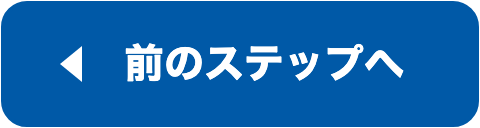](matlab:open('Step11_Setting.mlx'))　　[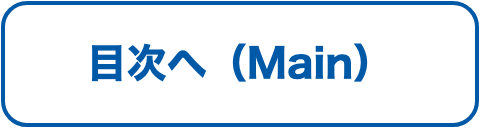](matlab:open('Main.mlx'))